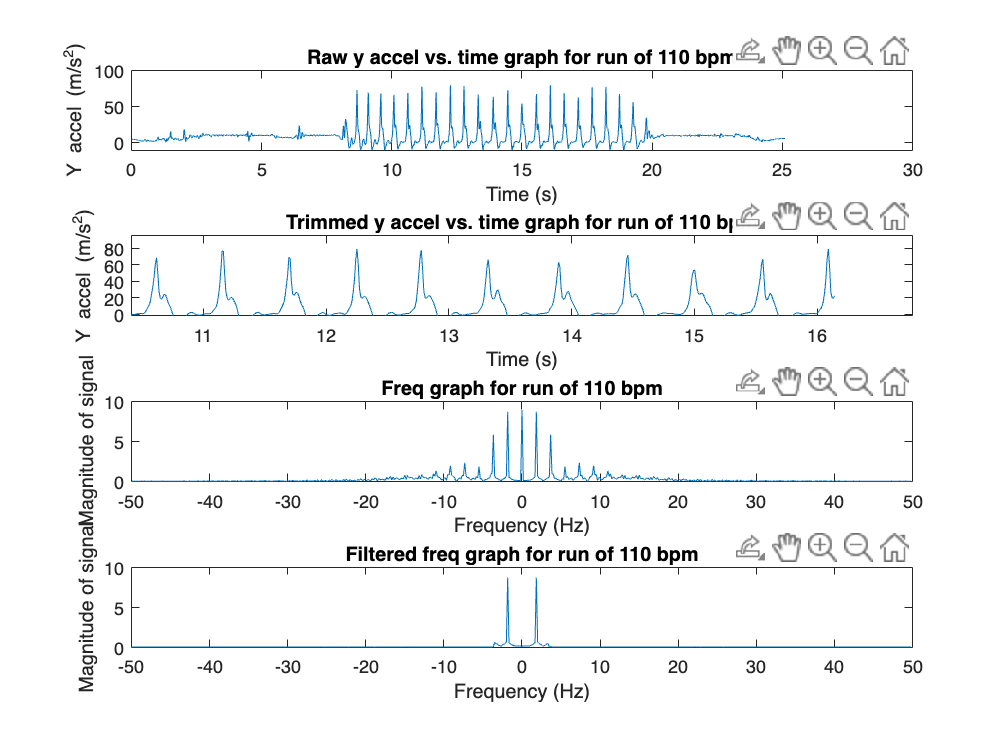

processAndPlotData('110_bpm.csv', 110, 10, 16, false, true)

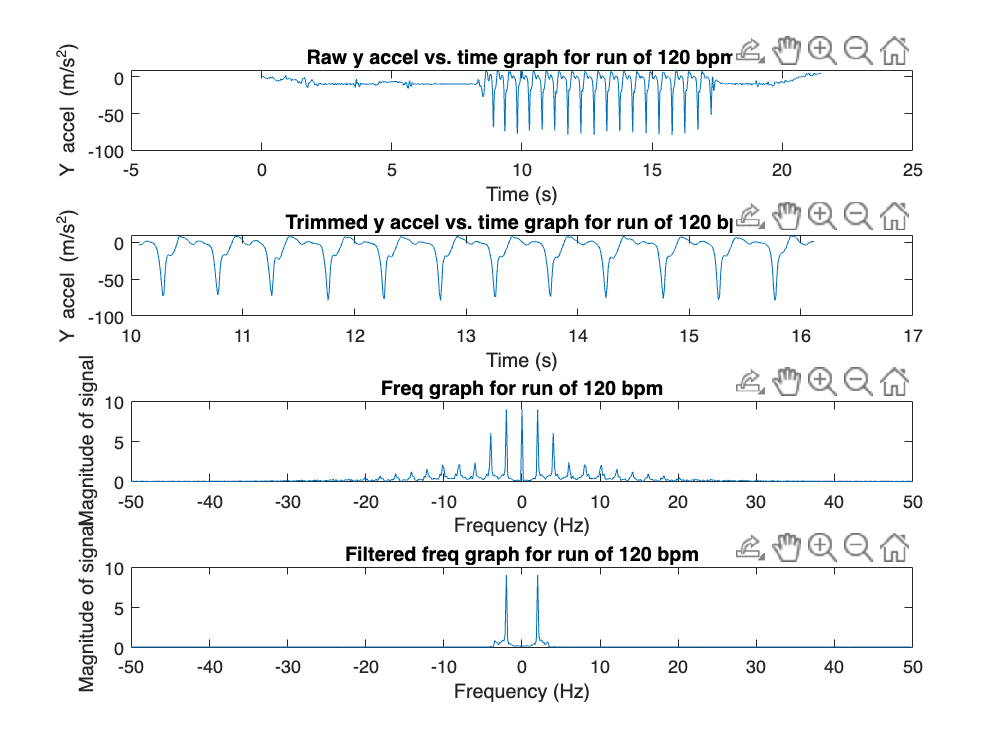

processAndPlotData('120_bpm.csv', 120, 10, 16, false, true)

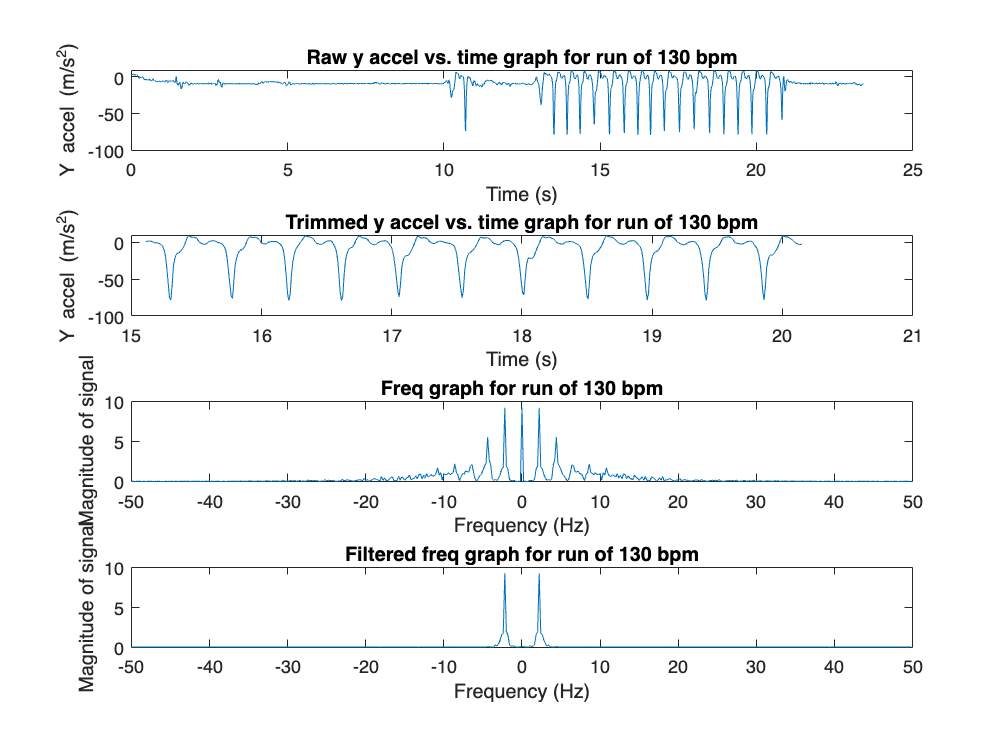

processAndPlotData('130_bpm.csv', 130, 15, 20, false, true)

ans = 2.4000

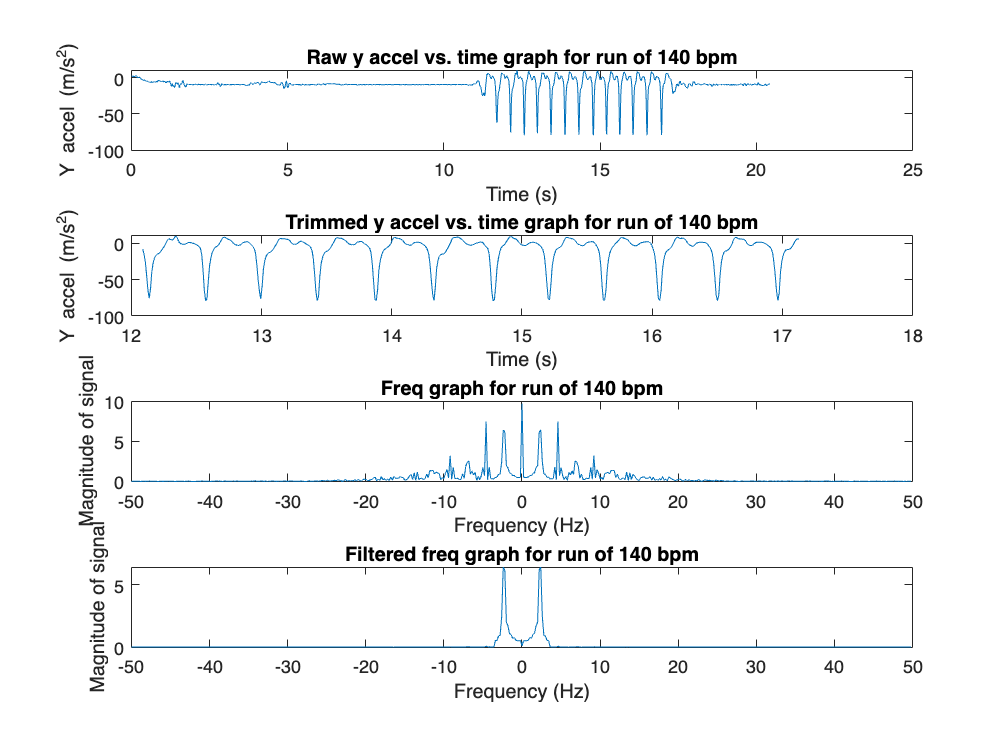

processAndPlotData('140_bpm.csv', 140, 12, 17, false, true)

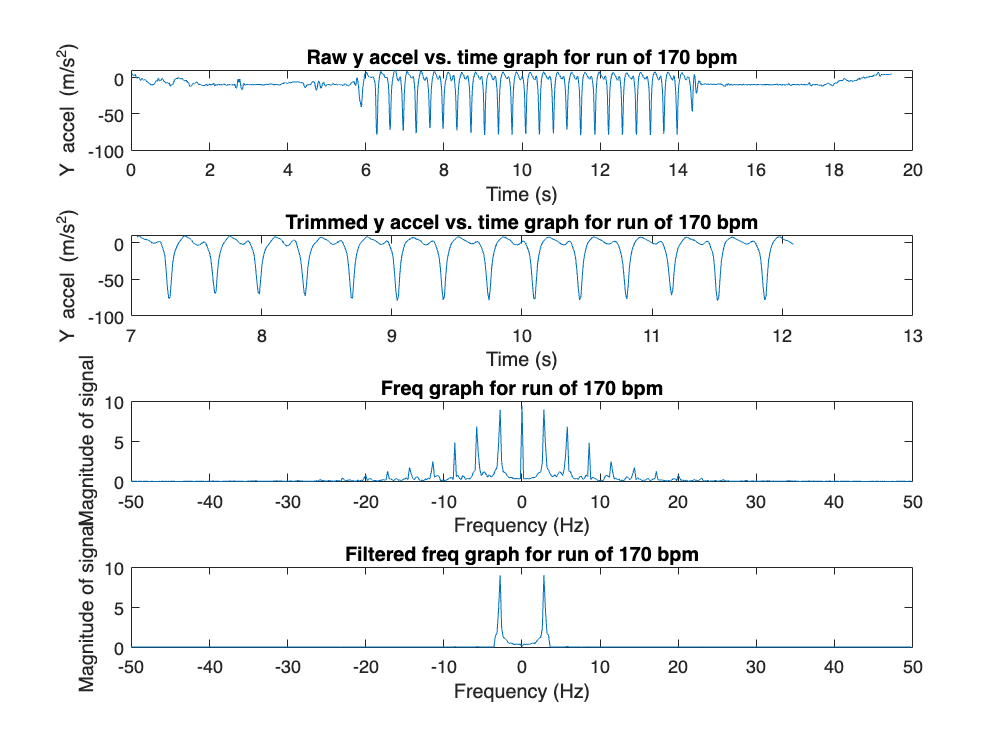

processAndPlotData('170_bpm.csv', 170, 7, 12, false, true)

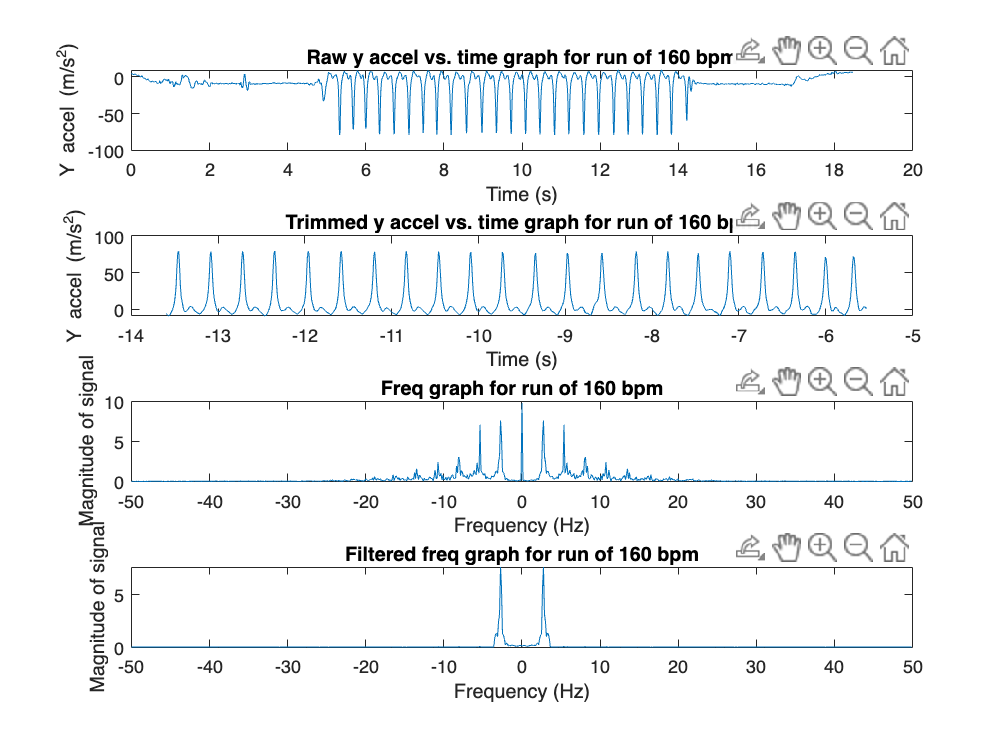

processAndPlotData('160_bpm.csv', 160, 5.5, 13.5, true, true)

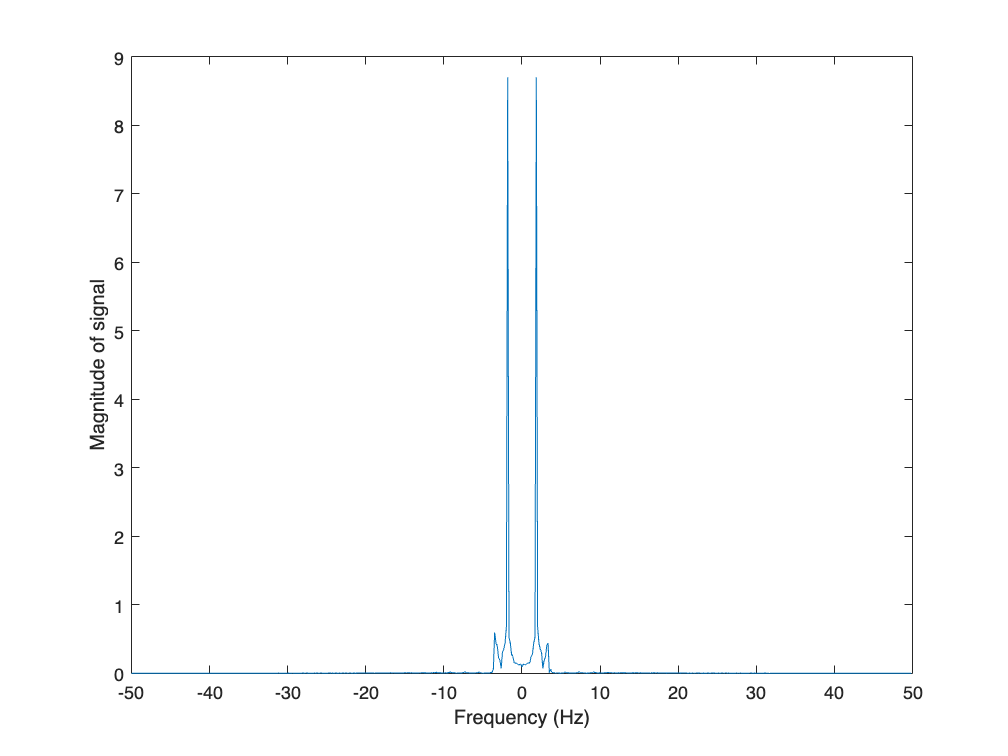

freq_value = 1.8333

calculated_bpm = 110.0000

ans = 110.0000

getFrequencyAndBpm('110_bpm.csv', 110, 10, 16)

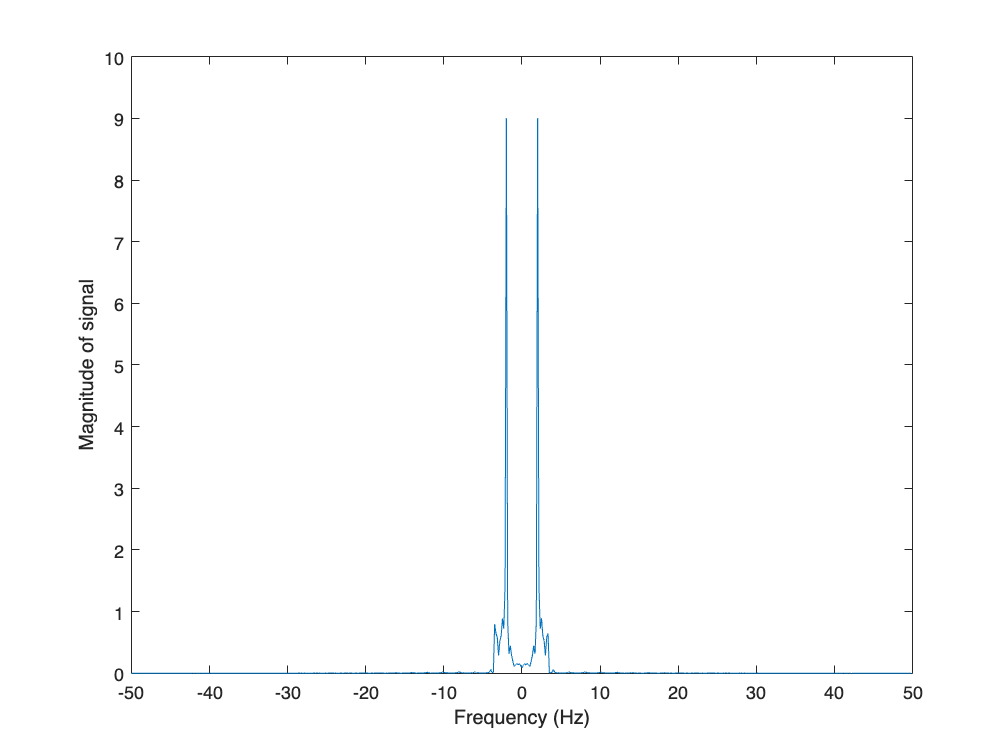

freq_value = 2.0000

calculated_bpm = 120.0000

ans = 120.0000

getFrequencyAndBpm('120_bpm.csv', 120, 10, 16)

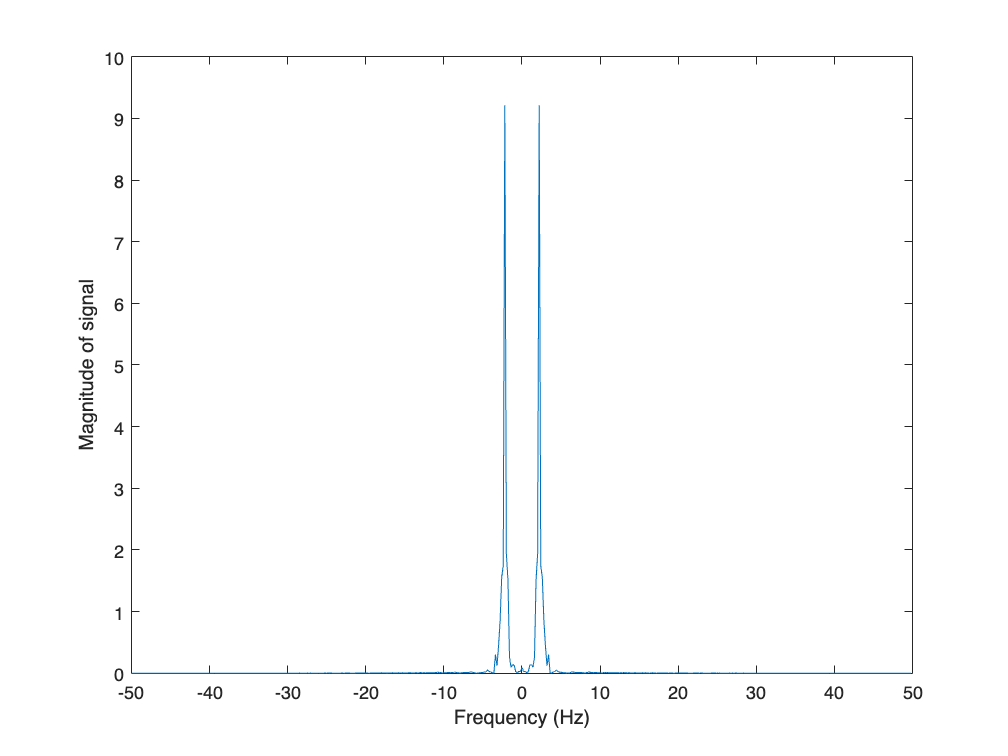

freq_value = 2.2000

calculated_bpm = 132.0000

ans = 132.0000

getFrequencyAndBpm('130_bpm.csv', 130, 15, 20)

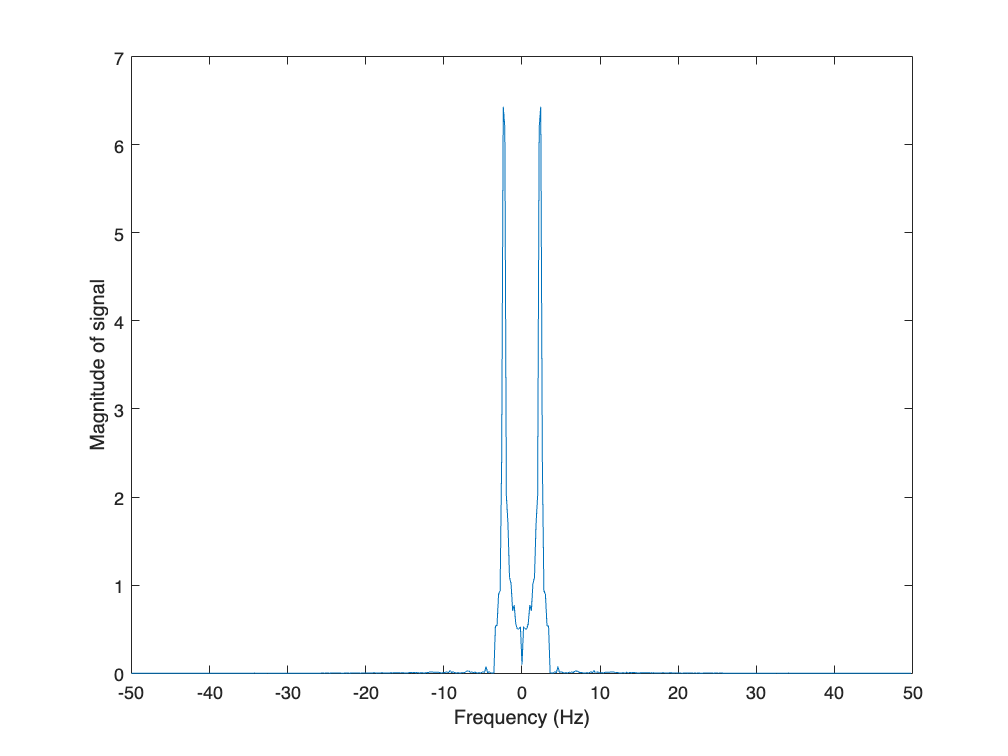

freq_value = 2.4000

calculated_bpm = 144.0000

ans = 144.0000

getFrequencyAndBpm('140_bpm.csv', 140, 12, 17)

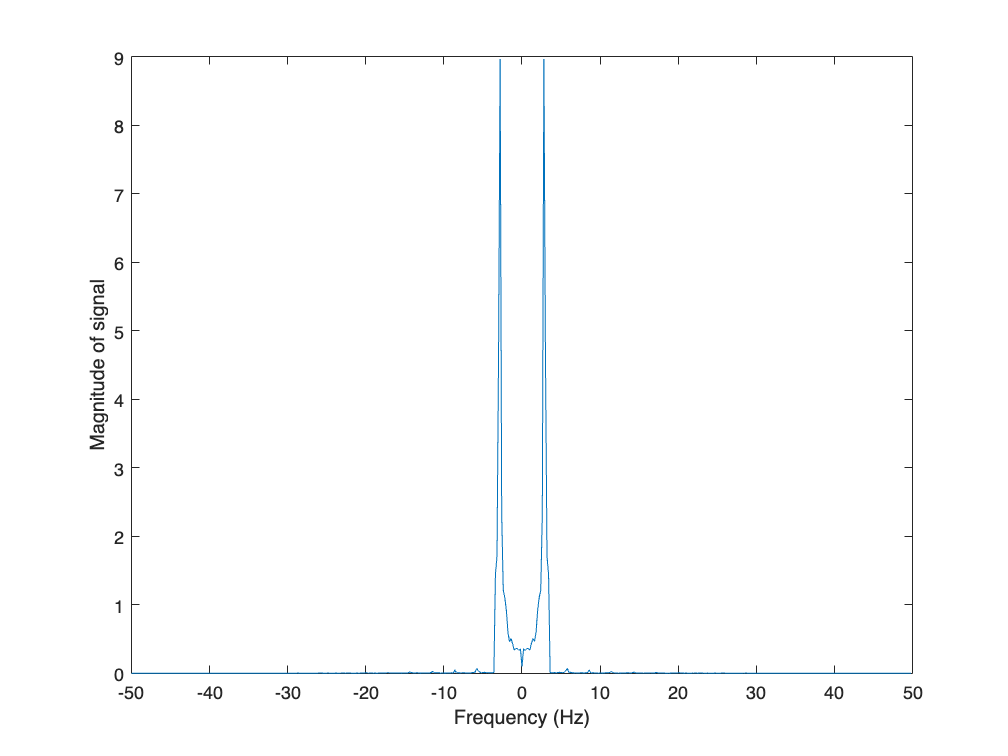

freq_value = 2.8000

calculated_bpm = 168.0000

ans = 168.0000


getFrequencyAndBpm('170_bpm.csv', 170, 7, 12)

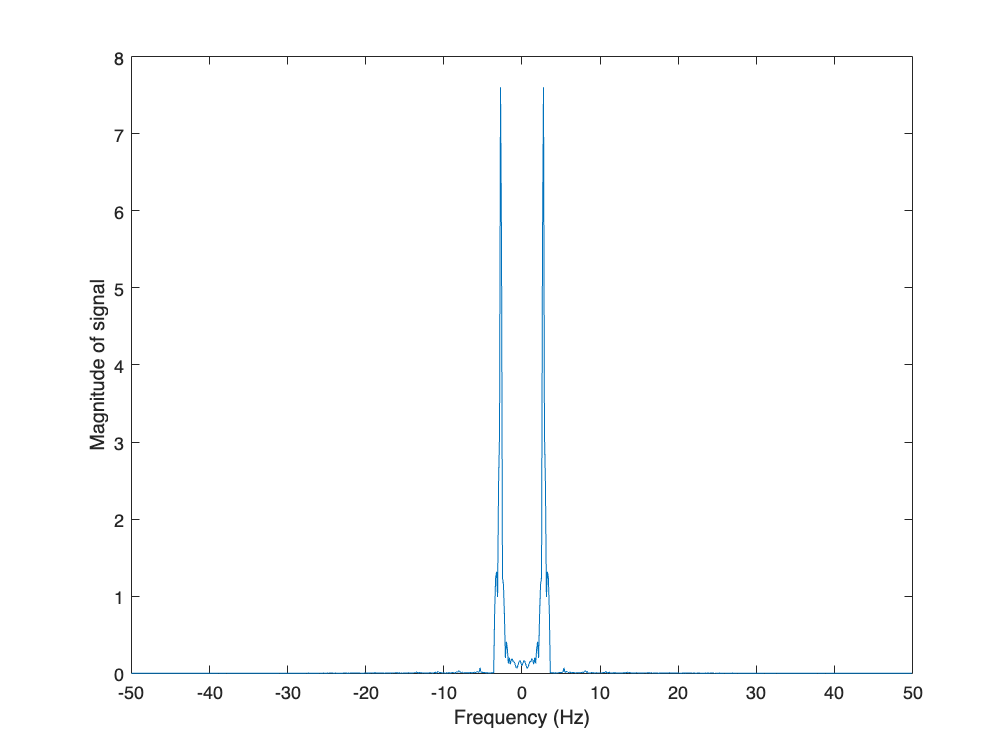

freq_value = 2.7500

calculated_bpm = 165

ans = 165

getFrequencyAndBpm('160_bpm.csv', 160, 5.5, 13.5)

function plotData(csv_filename)
    raw_data = readtable(csv_filename);
    plot(raw_data.t, raw_data.a_y)
end

% todo get most prominent peak

function [calculated_bpm, freq_value] = getFrequencyAndBpm(csv_filename, known_bpm, t_start, t_end)
    clf;
    raw_data = readtable(csv_filename);
    t_trimmed = raw_data.t(t_start * 100:t_end * 100);
    a_y_trimmed = raw_data.a_y(t_start * 100:t_end * 100);
    freq_value = make_freq_plot_suppress(a_y_trimmed, 100)
    calculated_bpm = freq_value * 60
end

function processAndPlotData(csv_filename, known_bpm, t_start, t_end, isFlipped, showAll)
    clf;
    raw_data = readtable(csv_filename);
    t_trimmed = raw_data.t(t_start * 100:t_end * 100);
    a_y_trimmed = raw_data.a_y(t_start * 100:t_end * 100);
    if isFlipped
        t_trimmed = t_trimmed * -1;
        a_y_trimmed = a_y_trimmed * -1;
    end

    if showAll
        % plot raw data
        subplot(4,1,1);
        plot(raw_data.t, raw_data.a_y)
        xlabel("Time (s)")
        ylabel("Y accel (m/s^2)")
        title("Raw y accel vs. time graph for run of " + known_bpm + " bpm")
    end

    % plot trimmed data
    subplot(4,1,2);
    plot(t_trimmed, a_y_trimmed)
    xlabel("Time (s)")
    ylabel("Y accel (m/s^2)")
    title("Trimmed y accel vs. time graph for run of " + known_bpm + " bpm")
    
    if showAll
        % plot frequency graph without suppression
        subplot(4,1,3);
        make_freq_plot(a_y_trimmed, 100)
        title("Freq graph for run of " + known_bpm + " bpm")
    end

    % plot frequency graph, suppressed
    subplot(4,1,4);
    make_freq_plot_suppress(a_y_trimmed, 100)
    title("Filtered freq graph for run of " + known_bpm + " bpm")
end